# TCLab On/Off Control

**Objective:** Generate data from an On/Off controller and determine the parameters of a 2nd order underdamped model that best fits the response.

On/off control is used in most cooling and heating applications where the actuator can only be On or Off. Run the temperature control lab with On/Off control for 4 minutes to reach a setpoint of $40^\circ\text{C}$.

## 4 Minutes of On/Off Control

clc; clear all; close all;
tmp = matlab.desktop.editor.getActive;
directory = fileparts(tmp.Filename);
filename = "onoff.csv";
absolute_path = fullfile(directory, filename);

try % try to read from file first
    A = readmatrix(absolute_path)
    tm_ = A(:,1);
    T1_ = A(:,2);
    Q1_ = A(:,3);
    disp('TCLab Data read from file')
    
catch % if file can not be found, simulate
    try 
        n = 240;
        tm_ = zeros(n, 1);
        T1_ = ones(n, 1) * 23.0;
        Q1_ = zeros(n, 1);
        
        lab = tclab;
        tic;
        figure()
        for i =1:240
            pause(1)
            tm_(i) = toc;
            T1_(i) = lab.T1;
            if T1_(i) < 40.0
                Q1_(i) = 100;
            else
                Q1_(i) = 0;
            end
            lab.Q1(Q1_(i));
            
            subplot(2,1,1)
            plot(tm_(1:i), T1_(1:i), 'r.', 'DisplayName','T1')
            legend("Location","best")
            ylabel('Temperature (C)')
            subplot(2,1,2)
            plot(tm_(1:i), Q1_(1:i), 'r-', 'DisplayName', 'Q1')
            ylabel('Heater Setting')
            xlabel('Time (s)')
        end    
        A = [tm_, T1_, Q1_]
        writematrix(A, absolute_path, 'Delimiter', ',')
    catch
        lab.off
        clear lab
    end
    
end

Use a graphical method to fit ato the closed-loop response by finding $K_p$, $\zeta$, and $\tau_s$. Dead-time $\theta_p$ is not needed for this model.


$$\tau_s^2 \frac{d^2T_1}{dt^2} + 2 \zeta \tau_s \frac{dT_1}{dt} + T_1 = K_p \, Q_1$$


Follow the steps to obtain a graphical approximation of a step response of the underdamped (oscillating) second order system. An underdamped system implies that $0 \ge \zeta > 1$.

- Find $\Delta T_1$ from step response.

- Find $\Delta T_{SP}$ as the input to the step response.

- Calculate $K_p = \frac{\Delta T_{SP}}{\Delta T_{sp}$.

- Calculate damping factor $\zeta$ from overshoot OS or ecay ratio DR.

- Calculate $\tau_s
$ from equations for rise time $t_r$, peak time $t_p$, or period P.

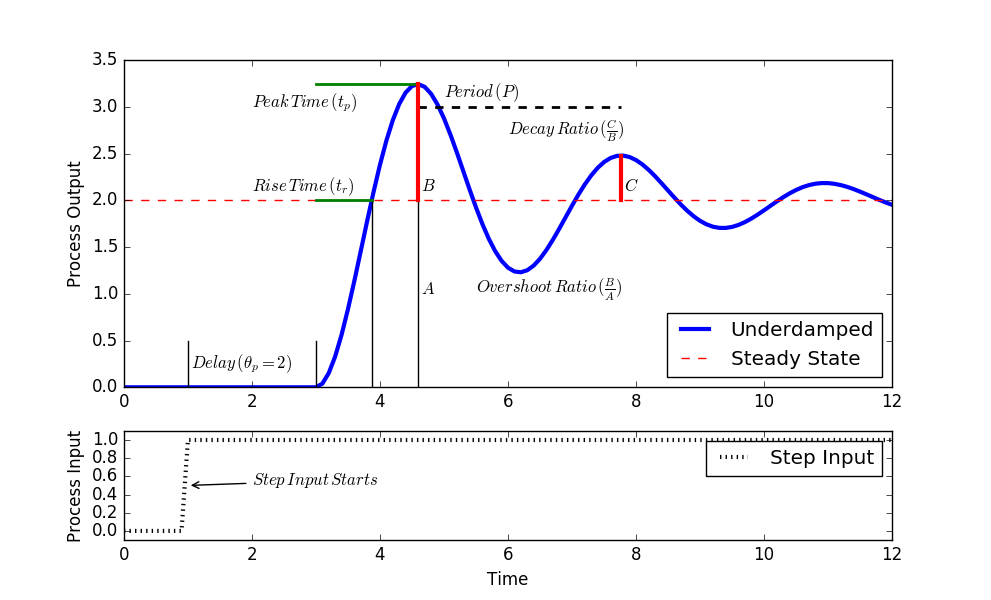

Add the underdamped ($0 \ge \zeta > 1$) analytic solution to data plot to compare the graphical fit to the data. See Second Order Systems for additional information on analytic solutions.

viewSolution(false)

 
$$T'_1(t) = K_p \Delta T_{SP} \left( 1-e^{-\zeta\,t/\tau_s} \left[ \cos\left( \frac{t}{\tau_s}\sqrt{1-\zeta^2} \right) + \frac{\zeta}{\sqrt{1-\zeta^2}} \sin\left( \frac{t}{\tau_s}\sqrt{1-\zeta^2} \right) \right] \right)$$


% graphic fit
Delta_SP = 20;
Delta_T1 = 22;
OS = (44-41)/(41-20);
tp = 86.0;
Kp = Delta_T1/Delta_SP;
lnOS2 = (log(OS))^2;
zeta = sqrt(lnOS2/(pi^2+lnOS2));
taus = tp * sqrt(1-zeta^2)/pi;
disp('Kp: ' + string(Kp))
disp('zeta: ' + string(zeta))
disp('taus: ' + string(taus))

%analytic solution


% plot
figure()
subplot(2,1,1)
plot(tm_, T1_, 'r.', 'DisplayName','TCLab')
hold on
plot(tm_, T1, 'r-', 'DisplayName','SOPDT')
hold off
legend("Location","best")
ylabel('Temperature (C)')
subplot(2,1,2)
plot(tm_(1:i), Q1_(1:i), 'r-', 'DisplayName', 'Q1')
ylabel('Heater Setting')
xlabel('Time (s)')

function viewSolution(view)
if view
	disp("T0 = T1_(1);" + newline + ...
	     "a = sqrt(1-zeta^2);" + newline + ...
	     "b = tm_/taus;" + newline + ...
	     "c = cos(a.*b);" + newline + ...
	     "d = (zeta/a)*sin(a*b);" + newline + ...
	     "T1 = Kp * Delta_SP * (1-exp(-zeta * b)*(c+d)) + T0")
end
end